# Flight Path Optimization

This script demonstrates the use of Optimization Toolbox™ to solve a simple pathfinding problem. 

We are given an airplane with a fixed airspeed and a vector field of wind in which to navigate. The objective is to find the path which minimizes the time taken to travel from the starting point to the finish point.

We can also find the optimal path when an initial wind field evolves to a second wind field. We navigate by recomputing the path at each time step to account for the time-varying wind field.

## Set parameters

clear;
AirSpeed = 500;
sizeX = 50;
sizeY = 25;
numWayPoints = 5;
randomSeed = 50;
rng(randomSeed);
method ="pchip" ; % Interpolation method
integrationFineness = 101;

## Fixed Wind Field

### Generate a random wind field

pathAxes = axes;
W_x = makeWindFun(sizeX,sizeY);
W_y = makeWindFun(sizeX,sizeY);
[Xgrid,Ygrid] = meshgrid(0:sizeX,0:sizeY);
hq = quiver(pathAxes,Xgrid,Ygrid,W_x,W_y,"k");

hold(pathAxes,"on");

pathAxes.XLabel.String = "Units = 100 [km]";
pathAxes.XLim = [0 sizeX];
pathAxes.YLim = [0 sizeY];
pathAxes.DataAspectRatio = [1 1 1];

plot(pathAxes,[0 sizeX],[sizeY sizeY]/2,"k.","MarkerSize",16)

Add some color to make it more visible by generating an image from the favorability of the wind to use as the background.

L = (sqrt((Xgrid-sizeX).^2 + (Ygrid-sizeY/2).^2));
Favorability = ((sizeX-Xgrid).*W_x +  (sizeY/2-Ygrid).*W_y)./L;
Favorability(~isfinite(Favorability)) = 0;

h_im = imagesc(pathAxes,Favorability);
set(h_im,"Xdata",[0 sizeX],"Ydata",[0 sizeY]);
uistack(h_im,"bottom");

Change the colormap.

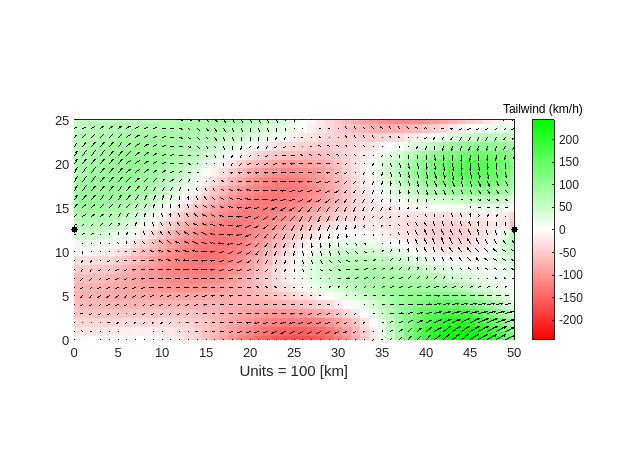

colormap(pathAxes,interp1([0,1,2],[1 0 0; 1 1 1; 0 1 0],0:0.01:2));
caxis(pathAxes,max(abs(Favorability(:)))*[-1 1]);

h_colorbar = colorbar(pathAxes);
title(h_colorbar,"Tailwind (km/h)")

### Generate waypoints in a straight line

Generate the points and plot.

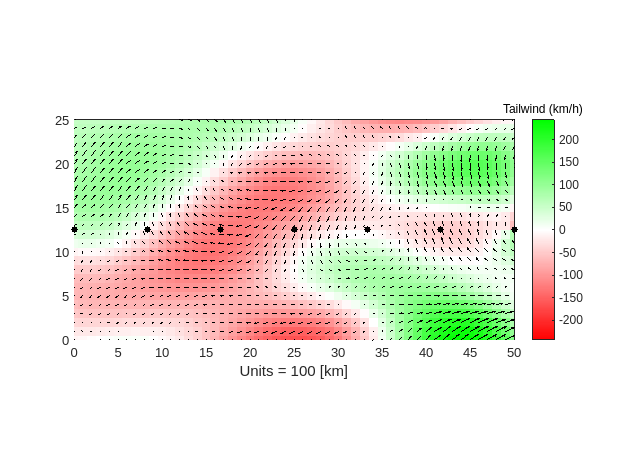

xWayPoints = linspace(0,sizeX,numWayPoints+2)';
yWayPoints = sizeY/2 * ones(numWayPoints+2,1);

h_wp = plot(pathAxes,xWayPoints,yWayPoints,"Color","k","LineStyle","none","Marker",".","MarkerSize",16);

Generate a continuous path from the points

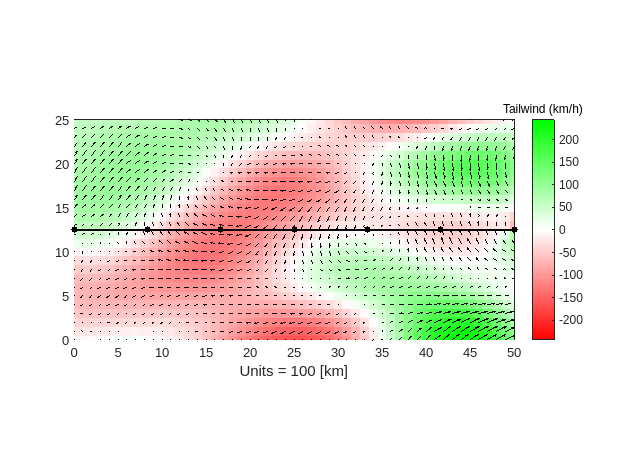

pathPoints = waypointsToPath([xWayPoints,yWayPoints],method,sizeX,sizeY,integrationFineness);
h_path = plot(pathAxes,pathPoints(:,1),pathPoints(:,2),"k","LineWidth",2);

Calculate the time taken

straightLineTime = getTimeFromPath(pathPoints,W_x,W_y,AirSpeed);

% Display in Hours/Minutes
fprintf("Straight Line Travel Time: %d hours, %.1f minutes\n",floor(straightLineTime),rem(straightLineTime,1)*60);

Straight Line Travel Time: 10 hours, 58.8 minutes


### Generate randomly chosen waypoints

xWayPoints = linspace(0,sizeX,numWayPoints+2)' .* (1+0.05*randn(size(xWayPoints)));
yWayPoints = sizeY/2 + (0.1*sizeY*randn(numWayPoints+2,1));
xWayPoints([1 end]) = [0 sizeX];
yWayPoints([1 end]) = sizeY/2;

Plot them

delete([h_wp h_path]);
h_wp = plot(pathAxes,xWayPoints,yWayPoints,"Color","k","LineStyle","none","Marker",".","MarkerSize",16);

Generate a continuous path from the waypoints

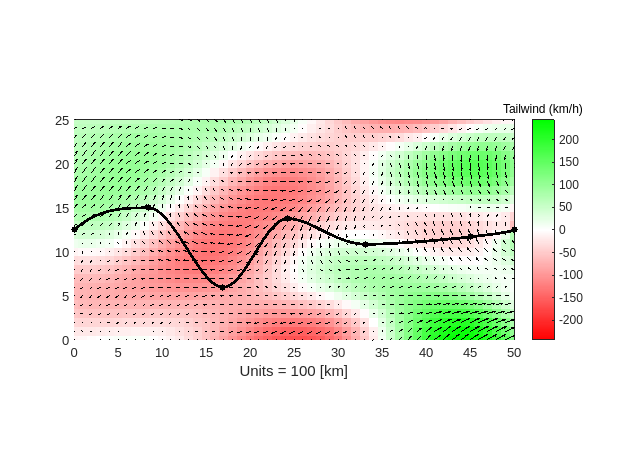

pathPoints = waypointsToPath([xWayPoints,yWayPoints],method,sizeX,sizeY,integrationFineness);
h_path = plot(pathAxes,pathPoints(:,1),pathPoints(:,2),"k","LineWidth",2);

Calculate the time taken

lineTime = getTimeFromPath(pathPoints,W_x,W_y,AirSpeed);
fprintf("Travel Time: %d hours, %.1f minutes\n",floor(lineTime),rem(lineTime,1)*60);

Travel Time: 12 hours, 48.8 minutes


### Find an optimal path using `fmincon`

Find the optimal waypoints. Define the objective function to minimize the time take on the path interpolated from the waypoints. 

objectiveFun = @(P) getTimeFromPath(P,W_x,W_y,AirSpeed,sizeX,sizeY,method,integrationFineness);

Set optimization options

opts = optimoptions("fmincon");
opts.Display = "iter";
opts.Algorithm = "sqp";
opts.MaxFunctionEvaluations = numWayPoints*500;

Use the straight-line waypoints for the initial point

xWayPoints = linspace(0,sizeX,numWayPoints+2)';
yWayPoints = sizeY/2 * ones(numWayPoints+2,1);
ipt = [xWayPoints(2:end-1)'; yWayPoints(2:end-1)'];
ipt = ipt(:);

Specify lower and upper bounds on the waypoints.

lb = zeros(size(ipt(:)));
ub = reshape([sizeX*ones(1,numWayPoints); sizeY*ones(1,numWayPoints)],[],1);

Do the optimization

optimalWayPoints = fmincon(objectiveFun,ipt(:),[],[],[],[],lb,ub,[],opts)

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          11    1.098005e+01     0.000e+00     1.000e+00     0.000e+00     1.424e-01  
    1          22    1.093160e+01     0.000e+00     1.000e+00     2.187e-01     1.504e-01  
    2          33    1.072614e+01     0.000e+00     1.000e+00     1.122e+00     1.027e-01  
    3          44    1.052410e+01     0.000e+00     1.000e+00     2.919e+00     7.307e-02  
    4          55    1.051278e+01     0.000e+00     1.000e+00     2.692e-01     6.192e-02  
    5          66    1.048868e+01     0.000e+00     1.000e+00     4.236e-01     3.867e-02  
    6          77    1.045732e+01     0.000e+00     1.000e+00     6.394e-01     3.108e-02  
    7          88    1.042535e+01     0.000e+00     1.000e+00     8.341e-01     6.914e-02  
    8         103    1.042173e+01     0.000e+00     2.401e-01     2.526e+00     6.

optimalWayPoints =    14.3502
   15.3226
   22.5796
   12.0004
   25.0000
   10.7207
   35.1596
    8.4907
   47.7322
   12.3642


optimalWayPoints = [0 sizeY/2; reshape(optimalWayPoints,2,[])'; sizeX sizeY/2];

### Plot the optimal solution

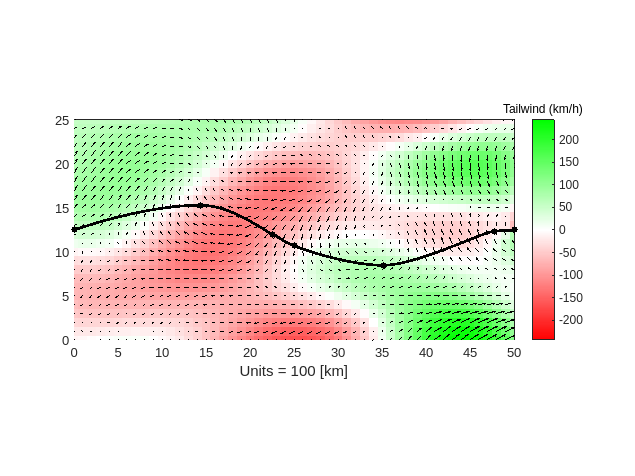

delete([h_wp h_path]);

xWayPoints = optimalWayPoints(:,1);
yWayPoints = optimalWayPoints(:,2);
h_wp = plot(pathAxes,xWayPoints,yWayPoints,"Color","k","LineStyle","none","Marker",".","MarkerSize",16);

pathPoints = waypointsToPath([xWayPoints,yWayPoints],method,sizeX,sizeY,integrationFineness);
h_path = plot(pathAxes,pathPoints(:,1),pathPoints(:,2),"k","LineWidth",2);

lineTime = getTimeFromPath(pathPoints,W_x,W_y,AirSpeed);
fprintf("Optimal Travel Time: %d hours, %.1f minutes\n",floor(lineTime),rem(lineTime,1)*60);

Optimal Travel Time: 10 hours, 17.8 minutes


## Time-Varying Wind Field

### Generate two random wind fields

The wind field at each time step is a convex combination of the two windfields, changing from the initial to the final wind field.

W_x0 = makeWindFun(sizeX,sizeY);
W_y0 = makeWindFun(sizeX,sizeY);
W_x1 = makeWindFun(sizeX,sizeY);
W_y1 = makeWindFun(sizeX,sizeY);

try
    delete([hq h_wp h_path])
catch
end

[Xgrid,Ygrid] = meshgrid(0:sizeX,0:sizeY);
hq = quiver(pathAxes,Xgrid,Ygrid,W_x0,W_y0,"k");

Add some color to make it more visible

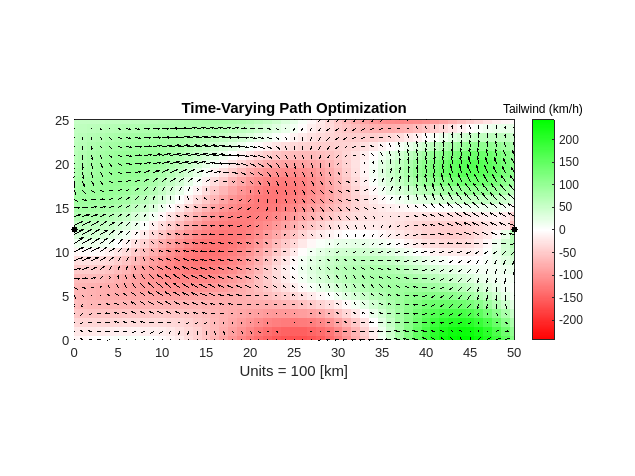

L = (sqrt((Xgrid-sizeX).^2 + (Ygrid-sizeY/2).^2));
Favorability = ((sizeX-Xgrid).*W_x0 +  (sizeY/2-Ygrid).*W_y0)./L;
Favorability(~isfinite(Favorability)) = 0;
Favorability0 = Favorability; %Record this so we can reuse it later

Favorability = ((sizeX-Xgrid).*W_x1 +  (sizeY/2-Ygrid).*W_y1)./L;
Favorability(~isfinite(Favorability)) = 0;
Favorability1 = Favorability; %Record this so we can reuse it later

hold(pathAxes,"on");
h_im = imagesc(pathAxes,Favorability0); % This will be the background for the vector field
set(h_im,"Xdata",[0 sizeX],"Ydata",[0 sizeY]);
uistack(h_im,"bottom");

title(pathAxes,"Time-Varying Path Optimization")

### Re-calculate the solution at each time step

In this optimization, we will assume that the x location of each waypoint is equally spaced, and we only optimize over the y values.

opts = optimoptions("fmincon");
opts.Display = "off";
opts.Algorithm = "sqp";

Initial point for first time step

X_points = linspace(0,sizeX,numWayPoints+2)';
x_opt = sizeY/2*ones(numWayPoints,1);
ystart = sizeY/2;

02% Percent Complete


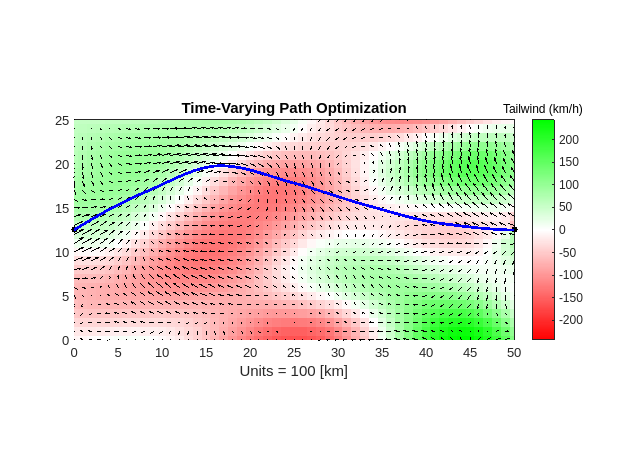

05% Percent Complete
08% Percent Complete
10% Percent Complete
12% Percent Complete
15% Percent Complete
18% Percent Complete
20% Percent Complete
22% Percent Complete
25% Percent Complete
28% Percent Complete
30% Percent Complete
32% Percent Complete
35% Percent Complete
38% Percent Complete
40% Percent Complete
43% Percent Complete
45% Percent Complete
48% Percent Complete
50% Percent Complete
52% Percent Complete
55% Percent Complete
58% Percent Complete
60% Percent Complete
62% Percent Complete
65% Percent Complete
68% Percent Complete
70% Percent Complete
73% Percent Complete
75% Percent Complete
78% Percent Complete
80% Percent Complete
82% Percent Complete
85% Percent Complete
88% Percent Complete
90% Percent Complete
92% Percent Complete
95% Percent Complete
98% Percent Complete
100% Percent Complete


timeStep = 1/40;
K_PointListX = cell(40);
K_PointListY = cell(40);
K_k = cell(40);
kctr = 1;

for time = 0: timeStep : 1-timeStep
    fprintf("%02.f%% Percent Complete\n",kctr*timeStep*100);
    W_x = (1-time)*W_x0 + time*W_x1;
    W_y = (1-time)*W_y0 + time*W_y1;
    
    % Make initial point based on the previous solution
    xstart = sizeX*time;
    points = [X_points [ystart; x_opt; sizeY/2]];
    X_points_old = X_points;
    X_points = linspace(xstart,sizeX,numWayPoints+2)';
    xy0 = interp1(X_points_old,points(:,2),X_points(2:end-1),method,"extrap");
    ystart = interp1(X_points_old,points(:,2),xstart,method,"extrap");
    
    lb = zeros(size(xy0(:)));
    ub = sizeY*ones(numWayPoints,1);
    
    % Define and solve the new optimization problem
    objectiveFun = @(P) ...
        calculateTimeIntermediate(P,W_x,W_y,xstart,ystart,AirSpeed,sizeX,sizeY,method,integrationFineness);
    x_opt = fmincon(objectiveFun,xy0(:),[],[],[],[],lb,ub,[],opts);
       
    points = [X_points [ystart; x_opt; sizeY/2]];
    PointList = waypointsToPath(points,method,sizeX,sizeY,integrationFineness);
    
    K_PointListX{kctr} = PointList(:,1);
    K_PointListY{kctr} = PointList(:,2);
    K_k{kctr} = time;
    kctr = kctr+1;
    if time == 0
        plot(pathAxes,PointList(:,1),PointList(:,2),"b","LineWidth",2);
        drawnow;
    end
end

### Plot the results

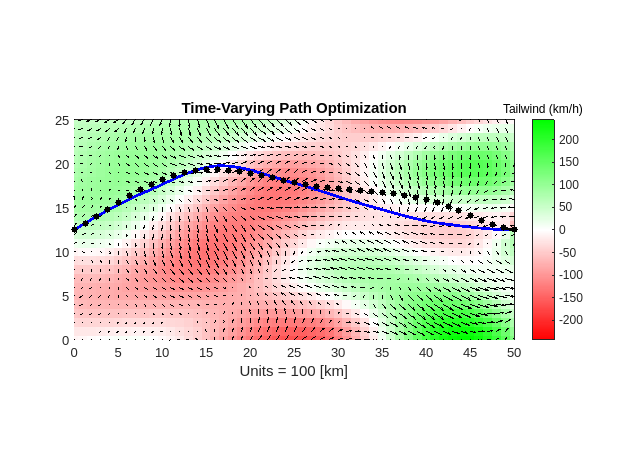

% pause;

for kk = 1:kctr-1
    time = K_k{kk};
    W_x = (1-time)*W_x0 + time*W_x1;
    W_y = (1-time)*W_y0 + time*W_y1;
    
    set(hq,"Udata",W_x,"Vdata",W_y);
    try 
        delete(hthis)
    catch
    end
    hthis = plot(pathAxes,K_PointListX{kk},K_PointListY{kk},"k","LineWidth",2);
    if kk == 1
        plot(pathAxes,K_PointListX{kk},K_PointListY{kk},"b","LineWidth",2);
        pause(1);
    end
    
    %Update the background image, as well as the path line
    plot(pathAxes,K_PointListX{kk}(1),K_PointListY{kk}(1),"k.","MarkerSize",16);
    Favorability = ((sizeX-Xgrid).*W_x +  (sizeY/2-Ygrid).*W_y)./L;
    Favorability(~isfinite(Favorability)) = 0;
    set(h_im,"Cdata",Favorability);
    
    drawnow
end

## Helper Functions

### makeWindFun

function iWind = makeWindFun(SZX,SZY)
% This is just a helper function to make a random scalar function. This is
% called twice to generate a random wind field.

windFineness = 0.1;
if ~exist("SZX","var")
    SZX = 50;
    SZY = 50;
end

N = 50; % Various parameters used in generating a random "smooth" matrix
NL = 40;
NP = 500;
rx = randn(NL,N);
rx = interpft(rx,NP);
ry = randn(NL,N);
ry = interpft(ry,NP);
I = (rx*ry');

[xgi,ygi] = meshgrid(linspace(1,2 + 498*windFineness,SZX+1),linspace(1,2 + 498*windFineness,SZY+1));
iWind = 10*interp2(1:500,1:500,I,xgi,ygi);
end

### waypointsToPath

function pathPoints = waypointsToPath(p,method,sizeX,sizeY,fineness)
% Interpolate the curve based on the discrete waypoints to generate a
% continuous path.

nP = size(p,1);
pathPoints = [interp1(1:nP,p(:,1),linspace(1,nP,fineness)',method,"extrap") ...
    interp1(1:nP,p(:,2),linspace(1,nP,fineness)',method,"extrap")];

% Do not leave the box
pathPoints(:,1) = min(pathPoints(:,1),sizeX);
pathPoints(:,1) = max(pathPoints(:,1),0);
pathPoints(:,2) = min(pathPoints(:,2),sizeY);
pathPoints(:,2) = max(pathPoints(:,2),0);
end

### getTimeFromPath

function travelTime = getTimeFromPath(pathPoints,W_x,W_y,AirSpeed,sizeX,sizeY,method,integrationFineness)
% This is the main function that actually calculates the line integral
% along the path. This is the objective function for the optimizer.

% If we are called from the optimization routine (caller = "optimizer")
% then we need to interpolate the fine path from the input control points.
if isvector(pathPoints)
    pathPoints = [0 sizeY/2; reshape(pathPoints,2,[])'; sizeX sizeY/2];
    pathPoints = waypointsToPath(pathPoints,method,sizeX,sizeY,integrationFineness);
end

dP = diff(pathPoints);

% Interpolate the wind vector field at all the points in pathPoints.
V_wind = [interp2(W_x,pathPoints(1:end-1,1)+1,pathPoints(1:end-1,2)+1,"linear") ...
    interp2(W_y,pathPoints(1:end-1,1)+1,pathPoints(1:end-1,2)+1,"linear")];

% Dot product the wind (V_wind) with the direction vector (dP) to get
% the tailwind/headwind contribution
V_add = (sum(V_wind.*dP,2))./sqrt(sum(dP.^2,2));
dx = sqrt(sum(dP.^2,2))*100; %dx is the length of each subinterval in pathPoints
dt = dx./(AirSpeed+V_add);  %dT = dP/dV
travelTime = sum(dt);
end

### calculateTimeIntermediate

function totalTime = calculateTimeIntermediate(x,W_x,W_y,x0,y0,AirSpeed,sizeX,sizeY,method,integrationFineness)
% This calculates the time starting from a specified start point (x0,y0)
% It is used in the time-dependent version of this optimization problem.

L = numel(x);
X_points = linspace(x0,sizeX,L+2)';

points = [X_points [y0; x; sizeY/2]];

PointList = [interp1(X_points,points(:,1),linspace(x0,sizeX,integrationFineness)',method,"extrap") ...
    interp1(X_points,points(:,2),linspace(x0,sizeX,integrationFineness)',method,"extrap")];

PointList(PointList < 0) = 0;
PointList(:,1) = min(PointList(:,1),sizeX);
PointList(:,2) = min(PointList(:,2),sizeY);

dP = diff(PointList);

V_wind = [interp2(W_x,PointList(1:end-1,1)+1,PointList(1:end-1,2)+1,"linear")...
    interp2(W_y,PointList(1:end-1,1)+1,PointList(1:end-1,2)+1,"linear")];

% Dot product the wind (V_wind) with the direction vector (dP)
V_add = (sum(V_wind.*dP,2))./sqrt(sum(dP.^2,2));

dx = sqrt(sum(dP.^2,2)); % dx is the length of each subinterval in plist
dT = dx./(AirSpeed+V_add);  % dT = dP/dV
totalTime = 100*sum(dT);
end

Copyright 2012-2019 The MathWorks, Inc. 